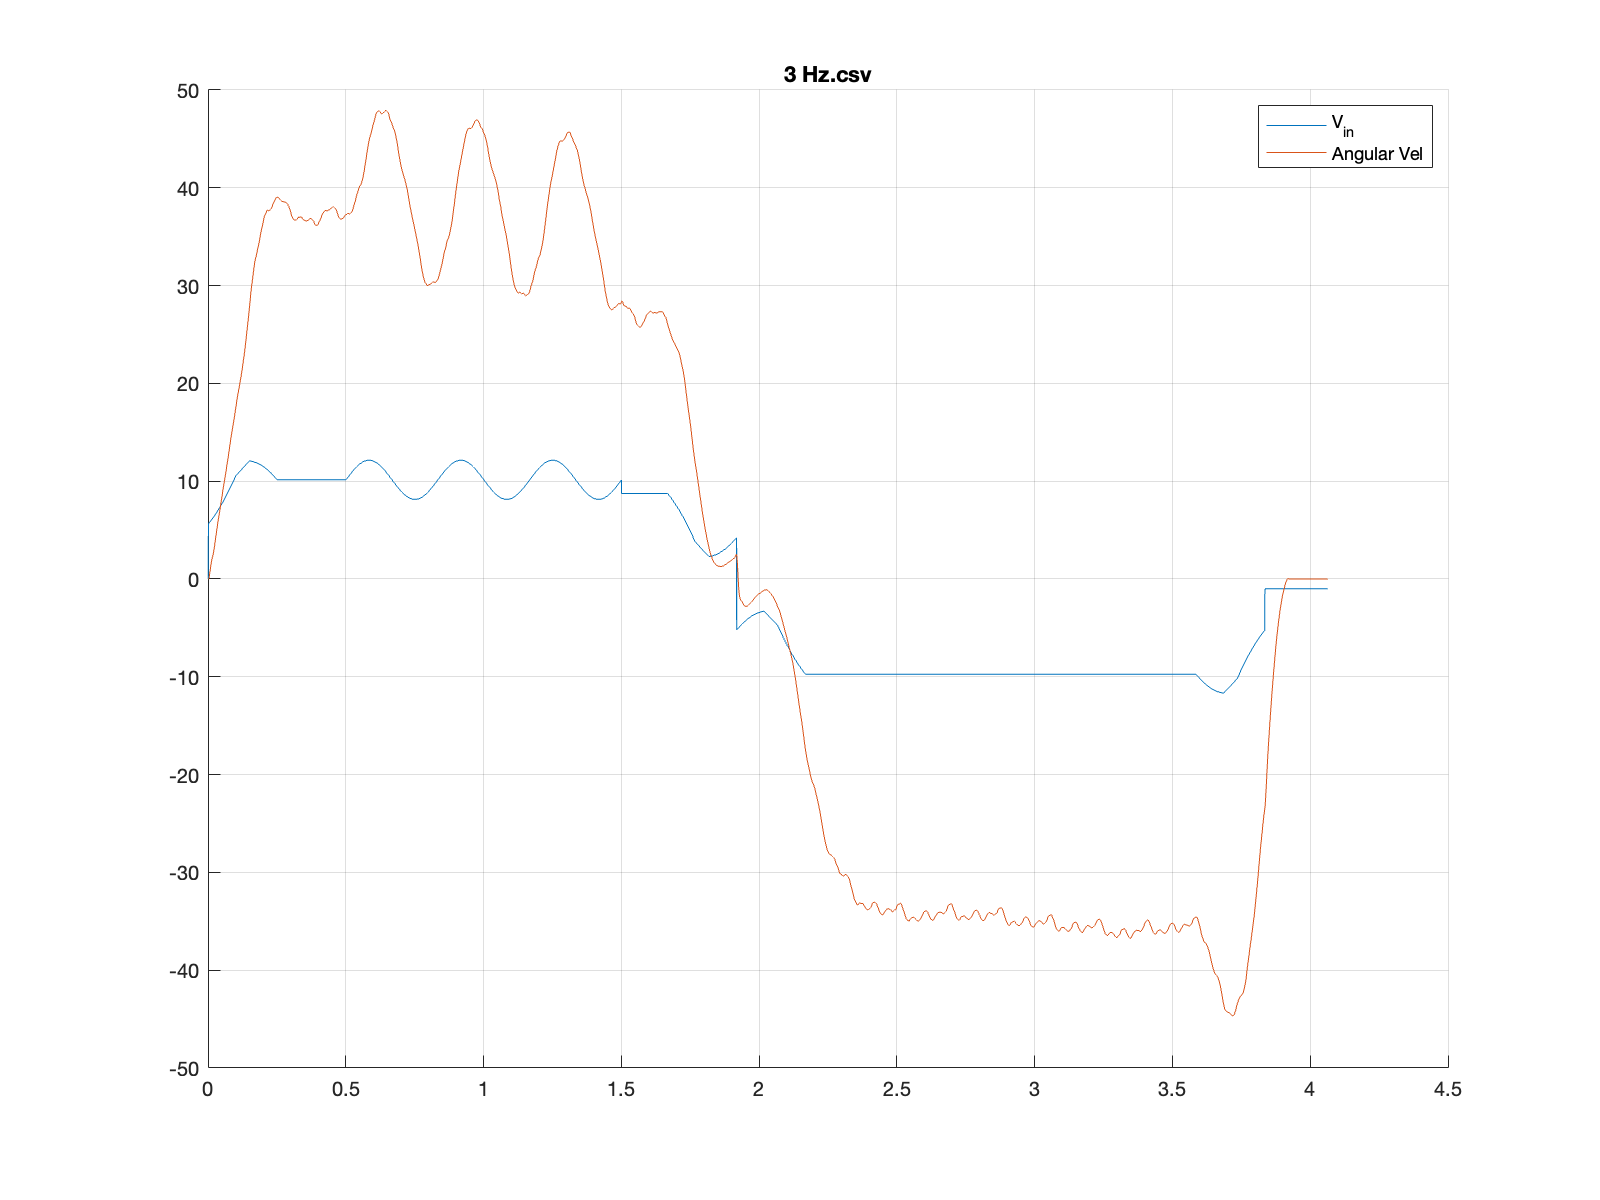

Error using ginput
Interrupted by figure deletion

csvFileName = '2 Hz.csv'; 

FILENAMES = {'2 Hz.csv','3 Hz.csv','4 Hz.csv','5 Hz.csv','6 Hz.csv','7 Hz.csv','8 Hz.csv','9 Hz.csv','10 Hz.csv','20 Hz.csv','30 Hz.csv','40 Hz.csv','50Hz.csv','60Hz.csv','70Hz.csv'};

MAGNITUDES = []; 
TIME_DIFFS = []; 

for i=1:15
dataTable = readtable(FILENAMES{i}); 
dataTable = dataTable(6:end-1,:);
pitch = 0.02;


sg = 0.887; % A/v 
kt = 0.72; % Nm/A 
Je = 5.9054E-4;
% name | enc1 pos | enc2 pos | enc 1 vel | enc 2 vel | V sig 

time = table2array(dataTable(:,"Var1"))/1000;
enc1_pos = table2array(dataTable(:, "Var2"));
enc2_pos = table2array(dataTable(:, "Var3")); 
enc1_vel = table2array(dataTable(:, "Var4")); 
vin = table2array(dataTable(:, "Var6")); 
%plot(time,enc1_pos)

%angular_vel = enc1_pos*10^-3 / pitch * 2 * pi;

phase_deg = enc1_pos *10^-3 / pitch * 2 * pi;

Ts = 0.5/1000;
[B,A]=butter(4,100*2*Ts);
filtered = filtfilt(B,A,enc1_pos*10^-3/pitch *2 * pi);
angular_vel = deriv(filtered,Ts); 

clf
% Define the new figure size
newWidth = 800;  % Width in pixels
newHeight = 600; % Height in pixels

% Create a new figure with the specified size
figure('Position', [100, 100, newWidth, newHeight]);
title(FILENAMES{i})
hold on; 
grid on; 
plot(time, vin*10);
plot(time, angular_vel)
legend("V_{in}", "Angular Vel")
%xlim([0.8,1.5])
%METHOD Up, Angular Velocity first, Then Up Vin
LOCATION = ginput(4);
Angular_diff = LOCATION(1,2) - LOCATION (2,2);
Voltage_diff = (LOCATION(3,2)-LOCATION(4,2))/10;
Magnitude = Angular_diff / Voltage_diff
MAGNITUDES = [MAGNITUDES Magnitude]
Time_diff = LOCATION(1,1) - LOCATION(3,1) 
TIME_DIFFS = [TIME_DIFFS Time_diff]
end

MAGNITUDES = [53.33333, 46.9231, 40.9091, 28.3333, 25.3571, 22.6923, 18.2143, 15.00 ,15.463, 7.1023, 5.3368, 4.1667, 2.6531, 2.3316, 1.9171]

MAGNITUDES =    53.3333   46.9231   40.9091   28.3333   25.3571   22.6923   18.2143   15.0000   15.4630    7.1023    5.3368    4.1667    2.6531    2.3316    1.9171


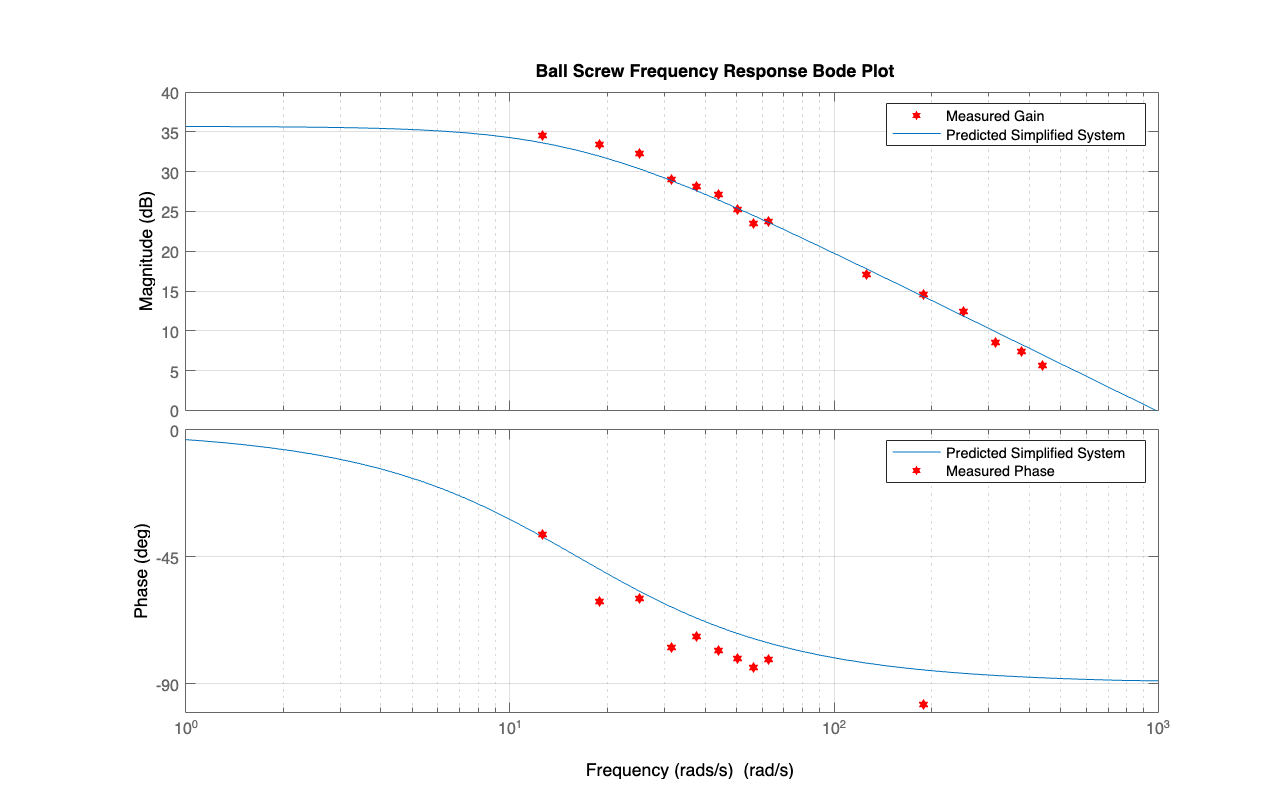

clf

TIME_DIFFS = [0.0518, 0.0565, 0.0415, 0.0429, 0.0339, 0.0311, 0.0282, 0.0260,0.0226, 0.0147, 0.0090, 0.0079, 0.0068, 0.005, 0.0058];
FREQUENCIES = [2 3 4 5 6 7 8 9 10 20 30 40 50 60 70];
%semilogx(FREQUENCIES*2 * pi,20*log10(MAGNITUDES),'<')
% Define the new figure size
newWidth = 800;  % Width in pixels
newHeight = 500; % Height in pixels

% Create a new figure with the specified size
figure('Position', [100, 100, newWidth, newHeight]);

scatter(FREQUENCIES*2 * pi,20*log10(MAGNITUDES),50, "hexagram",'r','filled')
hold on
%scatter(FREQUENCIES*2 * pi, 20*log10(MAGNITUDES), '>', 'filled', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
kt = 0.72;
Je=6.5E-4;
B=0.0105;
sg = 0.887 ;

s = tf('s');  

sys = sg * kt * 1/(Je * s + B);
legend("Measured Gain")
bode(sys)
scatter(FREQUENCIES * 2 * pi,-TIME_DIFFS .* FREQUENCIES * 2 * pi * 180/pi,50,"hexagram",'r','filled');
grid on 
ylim([-100 0])
% Customize the X-label's position to lower it
xlabel('Frequency (rads/s)', 'Position', [350, -20, 0]);
title('Ball Screw Frequency Response Bode Plot')

legend("Predicted Simplified System", "Measured Phase")
saveas(gcf, "bodeplot.png")